## Note: this file will take a preprocessed EEG dataset, determine an appropriate baseline, and feed it into a Gaussian Mixture Model (GMM)

## read in filtered data

% load in the filtered dataset
%allEDFs_filtered = allEDFs

## BASELINE 

% find index of first instance of "intubat" (intubation)
intubation_Index = find_indx(allEDFs_filtered, 'intubat')

intubation_Index = 259585


% find index of first instance of "incis" (incision)
incision_Index = find_indx(allEDFs_filtered, 'incis')

incision_Index = 678529

% run function to determine start index for each EEG channel
channels = {'EEGFp1_Cp3','EEGFpz_Cp3', 'EEGCp3_T3', 'EEGT3_O1', 'EEGFp2_Cp4', 'EEGFpz_Cp4', 'EEGCp4_T4', 'EEGT4_O2'}

channels = 1×8 cell array
    {'EEGFp1_Cp3'}    {'EEGFpz_Cp3'}    {'EEGCp3_T3'}    {'EEGT3_O1'}    {'EEGFp2_Cp4'}    {'EEGFpz_Cp4'}    {'EEGCp4_T4'}    {'EEGT4_O2'}


table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop
start_index = nan(1,table_size(1,2));
for k = 1:length(channels) 
    % TODO: once "EEG_PreProcess.mlx" is complete, modify method for determining start index. 
    % all of those repeated values should become nan so we just need to take values after that point.
    start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
end
start_index % check for baseline start

start_index =         4737        4737        4737        4737        4738        4737        4737        4737



% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
diffs = diff(start_index);
diffs = max(abs(diffs(diffs >= 0)));
if (diffs > 5)
    error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
end


## test

% entire baseline
test_full_filtered = allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index,:};
test_no_mode = allEDFs_nomode.data{'EEG'}{intubation_Index:incision_Index,:};
test_no_sat = allEDFs_nosaturation.data{'EEG'}{intubation_Index:incision_Index,:};
isnan(test_full_filtered)

ans = 418945×8 logical array
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0


null_values = find(isnan(test_full_filtered))

null_values =        10642
       10712
       10713
       10748
       10749
       10750
       11018
       11019
       11020
       11021


test_full_filtered(null_values(1:20000),:)

ans =        NaN       NaN   33.0014  -11.1765  -43.7655  -49.5980   15.9912  -10.6435
       NaN       NaN   37.8746  -11.3820       NaN       NaN   37.3872  -24.6461
       NaN       NaN   38.1182  -11.4353       NaN       NaN   37.8746  -24.4024
       NaN       NaN   36.8847   -7.2399  -35.6182  -40.2934   34.2654    2.6282
       NaN       NaN   39.5725   -9.5622  -41.7248  -49.3239   39.1461   -2.7475
       NaN       NaN   39.5954   -9.8059  -41.9685       NaN   40.1208   -4.4531
       NaN       NaN   42.7096    7.3871       NaN       NaN   49.3492   -4.6054
       NaN       NaN   42.7629    3.1155       NaN       NaN   49.6538   -5.4658
       NaN       NaN   37.1512   -5.8008       NaN       NaN   45.7477   -5.4810
       NaN       NaN   27.1385   -8.9759       NaN       NaN   35.4913   -4.7424


test_no_sat(null_values(1:20000,1),:)

ans =        NaN       NaN   33.0014  -11.1765  -43.7655  -49.5980   15.9912  -10.6435
       NaN       NaN   37.8746  -11.3820       NaN       NaN   37.3872  -24.6461
       NaN       NaN   38.1182  -11.4353       NaN       NaN   37.8746  -24.4024
       NaN       NaN   36.8847   -7.2399  -35.6182  -40.2934   34.2654    2.6282
       NaN       NaN   39.5725   -9.5622  -41.7248  -49.3239   39.1461   -2.7475
       NaN       NaN   39.5954   -9.8059  -41.9685       NaN   40.1208   -4.4531
       NaN       NaN   42.7096    7.3871       NaN       NaN   49.3492   -4.6054
       NaN       NaN   42.7629    3.1155       NaN       NaN   49.6538   -5.4658
       NaN       NaN   37.1512   -5.8008       NaN       NaN   45.7477   -5.4810
       NaN       NaN   27.1385   -8.9759       NaN       NaN   35.4913   -4.7424


explore = test_no_mode(null_values(1:20000,1),:)

explore =   -50.1005  -62.9153   33.0014  -11.1765  -43.7655  -49.5980   15.9912  -10.6435
  -51.4254  -63.6920   37.8746  -11.3820  -53.7249  -62.6793   37.3872  -24.6461
  -51.6690  -65.1539   38.1182  -11.4353  -56.4127  -62.9229   37.8746  -24.4024
  -50.1234  -54.8594   36.8847   -7.2399  -35.6182  -40.2934   34.2654    2.6282
  -54.2731  -61.2097   39.5725   -9.5622  -41.7248  -49.3239   39.1461   -2.7475
  -54.5168  -61.6133   39.5954   -9.8059  -41.9685  -52.4990   40.1208   -4.4531
  -52.1335  -56.3899   42.7096    7.3871  -53.3975  -63.4559   49.3492   -4.6054
  -54.8137  -59.8087   42.7629    3.1155  -60.7224  -71.5118   49.6538   -5.4658
  -54.9203  -60.2732   37.1512   -5.8008  -61.2097  -71.7021   45.7477   -5.4810
  -51.2655  -57.3417   27.1385   -8.9759  -59.2605  -68.0397   35.4913   -4.7424


explore(explore>60)

ans =    61.8290
   62.0726
   63.2452
   63.7326
   61.2960
   61.3341
   65.9711
   66.2148
   62.1488
   64.6082


explore(explore>70)


ans =

  0×1 empty double column vector



explore(explore>80)


ans =

  0×1 empty double column vector



explore(explore>90)


ans =

  0×1 empty double column vector



explore(explore>100)


ans =

  0×1 empty double column vector



explore(explore>200)


ans =

  0×1 empty double column vector




rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

window_analysis = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)

window_analysis = window_analysis(:,:,1) =

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN   49.4025       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   46.2426       NaN       NaN       NaN       NaN       NaN
       NaN   20.9252       NaN       NaN       NaN       NaN       NaN       NaN
       NaN   18.9760       NaN       NaN       NaN       NaN       NaN       NaN
  -33.3263   32.6436       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN  -45.4787       NaN       NaN       NaN       NaN       NaN   39.1005
       NaN       NaN       NaN       NaN       NaN       NaN     

analysis_nomode = windowed_data(incision_Index+1, size(allEDFs_nomode.data{'EEG'}(:,1)), allEDFs_nomode, window_size,channels)

analysis_nomode = analysis_nomode(:,:,1) =

 -200.3145   51.3518  101.7810  230.1496 -205.8729 -160.7508  171.4894  209.0201
 -239.3832   76.7453  100.9282  231.2461 -233.2157 -143.1695  116.7963  210.8551
 -243.7766   80.6514  130.2278  221.4846 -235.6598 -125.5958  171.4894  199.1368
 -165.6468   49.4025  132.1771  190.2281 -204.4033 -137.3142  202.7383  167.8879
 -170.0402   52.3264  100.9282  135.5426 -209.7790 -127.5451  203.2257  113.1947
 -138.7913   52.1741   46.2426   88.6692 -208.0658 -125.7176  191.5073   66.3214
 -127.0730   20.9252  -78.7606   82.8063 -217.8349 -135.4791  162.2077   66.4432
 -158.3219   18.9760 -149.0706   69.1387 -225.6471 -130.1111  -56.5422  -58.5523
  -33.3263   32.6436 -149.9234  -55.8645 -100.6439 -149.6416  -87.7911  -97.6211
 -103.6363   79.5245 -153.8295  -81.2504 -112.3622 -161.3600   68.4610  -85.9027
   83.8646  -45.4787 -208.5226  -51.9584  -81.1134 -166.7356  146.5832   39.1005
  240.1091  -92.3520 -222.1902 -169.1417  137.6365 -153.0604  201

analysis_nosat = windowed_data(incision_Index+1, size(allEDFs_nosaturation.data{'EEG'}(:,1)), allEDFs_nosaturation, window_size,channels)

analysis_nosat = analysis_nosat(:,:,1) =

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN   49.4025       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN   46.2426       NaN       NaN       NaN       NaN       NaN
       NaN   20.9252       NaN       NaN       NaN       NaN       NaN       NaN
       NaN   18.9760       NaN       NaN       NaN       NaN       NaN       NaN
  -33.3263   32.6436       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN  -45.4787       NaN       NaN       NaN       NaN       NaN   39.1005
       NaN       NaN       NaN       NaN       NaN       NaN       


Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

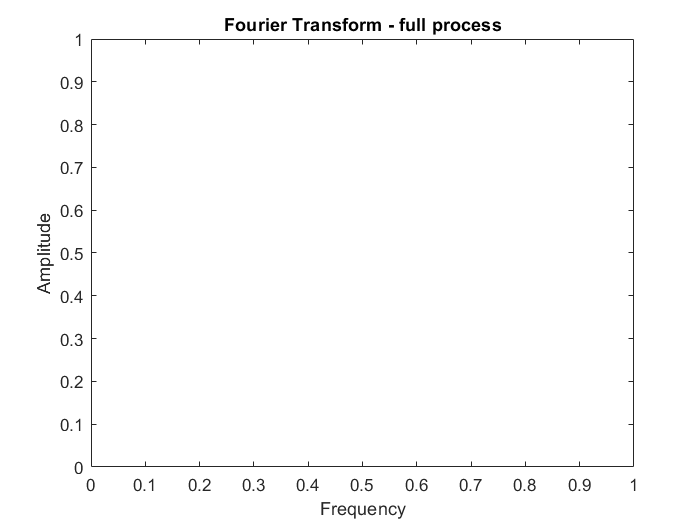

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform - full process')


transforms_analysis = fft(analysis_nomode, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

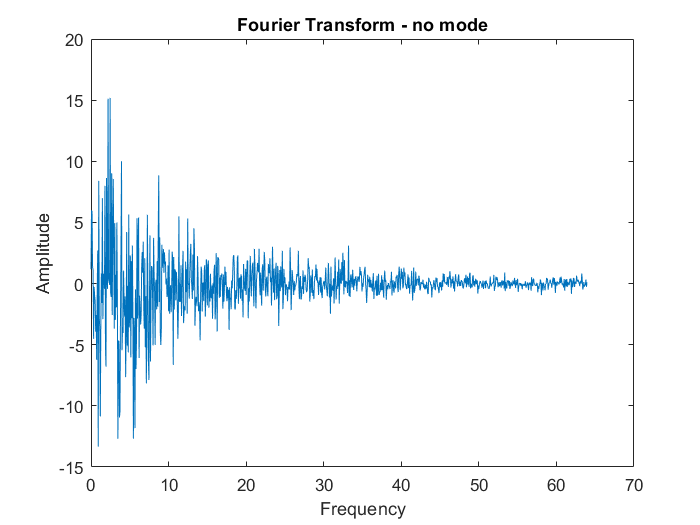

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform - no mode')


transforms_analysis = fft(analysis_nosat, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

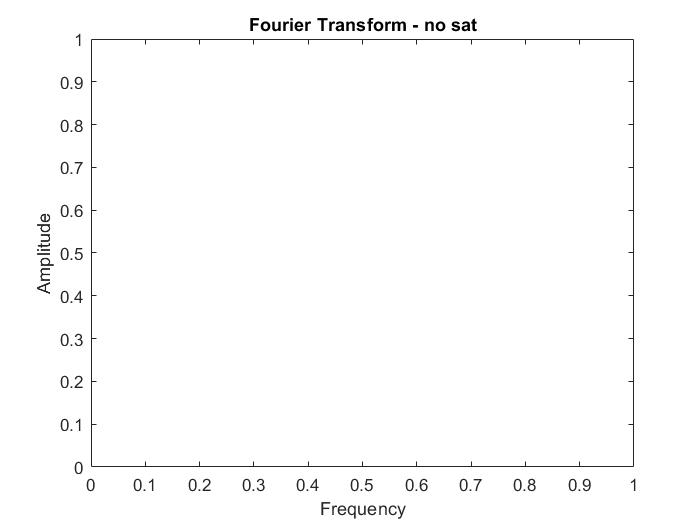

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform - no sat')

## baseline mean determination (single value/channel)

% baseline_preIntubation = nan(1,8);
% baseline_postIntubation = nan(1,8);
% baseline_Total = nan(1,8);
% for i = 1:table_size(1,2)
%     baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
%     baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
%     baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
% end
% baseline_preIntubation
% baseline_postIntubation
% baseline_Total

## baseline mean determination (15 sec window/channel)


% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel

rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

%preintubation_mean_baseline_window = mean_baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)
%postintubation_mean_baseline_window = mean_baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)
%total_mean_baseline_window = mean_baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)  

## baseline window determination (3D - for GMM)

%window_preintubation_baseline = windowed_data(start_index, intubation_Index, allEDFs_filtered, window_size,channels)
window_postintubation_baseline = windowed_data(intubation_Index, incision_Index, allEDFs_filtered, window_size,channels)
test_nomode = windowed_data(intubation_Index, incision_Index, allEDFs_nomode, window_size,channels)
test_nosat = windowed_data(intubation_Index, incision_Index, allEDFs_nosaturation, window_size,channels)
%window_total_baseline = windowed_data(start_index, incision_Index, allEDFs_filtered, window_size,channels)


## ANALYSIS 

% Note: from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline


## analysis window determination

window_analysis = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)
analysis_nomode = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_nomode, window_size,channels)
analysis_nosat = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_nosaturation, window_size,channels)


%gm = fitgmdist(preintubation_baseline_window, 1) % how do we know how many components a GMM should be?
%properties(gm); % list all properties for the GMM. Can be accessed using format "gm.NumVariables" (dot notation)
% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model


## gaussian mixture model



Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)
N = L % end point
f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))
xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

% spectral bands
 delta_analysis = spectral_bandpower(window_analysis, [1 3], Fs);
% delta_baseline = spectral_bandpower(window_postintubation_baseline, [1 3], Fs);
% theta_analysis = spectral_bandpower(window_analysis, [4 7], Fs);
% theta_baseline = spectral_bandpower(window_postintubation_baseline, [4 7], Fs);
% alpha_analysis = spectral_bandpower(window_analysis, [8 12], Fs);
% alpha_baseline = spectral_bandpower(window_postintubation_baseline, [8 12], Fs);
% beta_analysis = spectral_bandpower(window_analysis, [13 20], Fs);
% beta_baseline = spectral_bandpower(window_postintubation_baseline, [13 20], Fs);
% gamma_analysis = spectral_bandpower(window_analysis, [30 100], Fs); 
% gamma_baseline = spectral_bandpower(window_postintubation_baseline, [30 100], Fs);

spectral_bands = struct('delta', {spectral_bandpower(window_postintubation_baseline, [1 3], Fs),spectral_bandpower(window_analysis, [1 3], Fs)}, ...
    'theta',{spectral_bandpower(window_postintubation_baseline, [4 7], Fs), spectral_bandpower(window_analysis, [4 7], Fs)}, ...
    'alpha', {spectral_bandpower(window_postintubation_baseline, [8 12], Fs), spectral_bandpower(window_analysis, [8 12], Fs)}, ...
    'beta', {spectral_bandpower(window_postintubation_baseline, [13 20], Fs), spectral_bandpower(window_analysis, [13 20], Fs)}, ...
    'gamma', {spectral_bandpower(window_postintubation_baseline, [30 100], Fs), spectral_bandpower(window_analysis, [30 100], Fs)});



gm = fitgmdist(gamma_baseline(:,1:2), 1)
d8 = mahal(gm, gamma_baseline(:,1:2))
d9 = mahal(gm, gamma_analysis(1:219,1:2))
x = cluster(gm, delta_analysis(:,1:2))

% TODO: rn were looking at two channels, will need to look at all 8
% eventually
% TODO: optimize code eventually to increase speed -> create functions from
% various baseline determination methods. preallocate as well
% TODO: plot data meaningfully
% TODO: feedback from dr k
% TODO: more rigorous validation of mahal to determine if it is what we are
% looking for, as well as determining meaning of mahal distances. (also,
% are the mahal distances abnormal at alerts, as they should be?)

[P, nlogL] = posterior(gm, delta_baseline(:,1:2))

figure; 
gscatter(delta_baseline(:,1),delta_baseline(:,2), idx)
xlim([0 80])
ylim([0 80])
% can start with all of these dimensions and maybe go to less dimensions
% (principal component analysis)

%NOTE: GMM requires Statistics and Machine Learning Toolbox